**Homework 1 Phys4001**

Steven Henderson

9/12/2024

**1.**

People exhale, cough or sneeze particles ranging from 0.1 μm to 1000 μm in

diameter. Consider spherical droplets of diameters 2 μm (sometimes referred

to as aerosols) and 400 μm with the same density as water. The drag force

may be taken as $F_{\mathrm{Drag}} =-\mathrm{bv}-{\mathrm{cv}}^2$ where the expressions for b and c were

given in lecture. The motion is assumed to be one-dimensional, vertically

downward, and starting from rest.


$$b=6\pi \eta R$$



$$c=\frac{1}{2}c_D^{\;} \rho A$$


(i) In each case, solve for the vertical terminal velocity $v_t$ analytically, and

then calculate it numerically.

Terminal velocity is reached when $F_{\mathrm{gravity}} ={-F}_{\mathrm{Drag}}$ and therefore the object is under no acceleration.

$F_{\mathrm{gravity}} =\mathrm{mg}$ (assume g)


$$F_{\mathrm{Drag}} =-\mathrm{bv}-{\mathrm{cv}}^2 =-F_{\mathrm{gravity}} =-\mathrm{mg}$$


solve for velocity:


$${-\mathrm{cv}}^2 -\mathrm{bv}+\mathrm{mg}=0$$



$$v=\frac{b\pm \sqrt{{\left(b\right)}^2 -4\left(-c\right)\left(\mathrm{mg}\right)}}{-2c}=\frac{b\pm \sqrt{b^2 +4\mathrm{cmg}}}{-2c}$$


Droplet of 2 microns

diameters = [2 * 10^-6, 400 * 10^-6];
viscosity = 1.8*10^-5;
coefficient_of_drag = 0.47;
radius = diameters ./ 2;
density_water = 1000;
volume = 4/3 * pi * radius.^3;
mass = volume * density_water;
density_air = 1.225;
area = pi * radius.^2;
b = 6 * pi * viscosity * radius;
c = 0.5 * coefficient_of_drag * density_air * area;
g = 9.8;
v = (b - sqrt(b.^2 + 4*c.*mass*g)) ./ (-2*c)

v =     0.0001    2.2177


(ii) Determine whether laminar or turbulent flow dominates for each droplet

size.

*Laminar*


$$F=-\mathrm{bv}$$


*Turbulent*


$$F=-{\mathrm{cv}}^2$$


F_lam = -b.*v

F_lam = 1.0e-06 *

   -0.0000   -0.1505


F_turb = -c.*v.^2

F_turb = 1.0e-06 *

   -0.0000   -0.1779


(iii) Using Matlab, make a log-log plot of the vertical terminal velocity in

units of cm/s versus droplet diameter ranging from 0.1 μm to 10,000 μm.

[To create such a large span of diameters in Matlab you would want to

use a function called ‘logspace’. To make a log-log plot use the command

‘loglog(X,Y,LineSpec)’ instead of ‘plot(X,Y,LineSpec)’. Place 10 tic marks

per decade.] Note the change of slope where the smooth transition between

laminar and turbulent flow occurs. The reason for plotting the larger droplets

(up to 1 cm!) is to more clearly see the transition from laminar to turbulent

flow. If there is an updraft greater than the terminal velocity the droplet will

rise rather than fall, and horizontal air currents could carry them far away

from their original position.

0.1 * 10^-2

ans = 1.0000e-03

10000 * 10^-2

ans = 100

diameters_microns = logspace(-1, 4)

diameters_microns = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0007    0.0009    0.0011    0.0014    0.0018    0.0022    0.0028    0.0036    0.0045    0.0057    0.0072    0.0091    0.0115    0.0146    0.0184    0.0233    0.0295    0.0373    0.0471    0.0596    0.0754    0.0954    0.1207    0.1526    0.1931    0.2442    0.3089    0.3907    0.4942    0.6251    0.7906    1.0000


diameters = diameters_microns * 10^-6

diameters =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0010    0.0012    0.0015    0.0019    0.0024    0.0031    0.0039    0.0049    0.0063    0.0079    0.0100


viscosity = 1.8*10^-5

viscosity = 1.8000e-05

coefficient_of_drag = 0.47

coefficient_of_drag = 0.4700

radius = diameters ./ 2

radius =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0010    0.0012    0.0015    0.0020    0.0025    0.0031    0.0040    0.0050


volume = 4/3 * pi * radius.^3

volume = 1.0e-06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0009    0.0019    0.0038    0.0076    0.0154    0.0312    0.0632    0.1279    0.2587    0.5236


mass = volume * density

mass = 1.0e-03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0009    0.0019    0.0038    0.0076    0.0154    0.0312    0.0632    0.1279    0.2587    0.5236


area = pi * radius.^2

area = 1.0e-04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0007    0.0011    0.0017    0.0028    0.0045    0.0071    0.0114    0.0183    0.0293    0.0468    0.0749    0.1199    0.1918    0.3069    0.4909    0.7854


b = 6 * pi * viscosity * radius

b = 1.0e-05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0008    0.0010    0.0012    0.0015    0.0020    0.0025    0.0031    0.0040    0.0050    0.0063    0.0080    0.0101    0.0128    0.0162    0.0205    0.0259    0.0328    0.0414    0.0524    0.0663    0.0838    0.1060    0.1341    0.1696


c = 1/2 * coefficient_of_drag * density * area

c =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0007    0.0011    0.0018    0.0028    0.0045    0.0072    0.0115    0.0185


v_neg = (-1 * b - sqrt(b.^2 + 4*c.*mass*g)) ./ (2*c) * 100

v_neg =  -919.1490 -726.6832 -574.5189 -454.2172 -359.1062 -283.9110 -224.4616 -177.4607 -140.3018 -110.9243  -87.6989  -69.3378  -54.8231  -43.3502  -34.2839  -27.1226  -21.4713  -17.0200  -13.5271  -10.8065   -8.7173   -7.1549   -6.0389   -5.3007   -4.8731   -4.6918   -4.7027   -4.8662   -5.1570   -5.5608   -6.0710   -6.6864   -7.4101   -8.2480   -9.2089  -10.3040  -11.5469  -12.9535  -14.5424  -16.3348  -18.3549  -20.6303  -23.1919  -26.0750  -29.3192  -32.9691  -37.0750  -41.6936  -46.8886  -52.7316


v_pos = (-1 * b + sqrt(b.^2 + 4*c.*mass*g)) ./ (2*c) * 100

v_pos =     0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0008    0.0013    0.0021    0.0033    0.0053    0.0085    0.0136    0.0218    0.0348    0.0556    0.0887    0.1411    0.2234    0.3503    0.5399    0.8091    1.1659    1.6041    2.1074    2.6594    3.2507    3.8798    4.5511    5.2727    6.0553    6.9111    7.8535    8.8970   10.0575   11.3520   12.7994   14.4205   16.2385   18.2788   20.5701   23.1443   26.0374   29.2894   32.9456   37.0564   41.6789   46.8769   52.7225


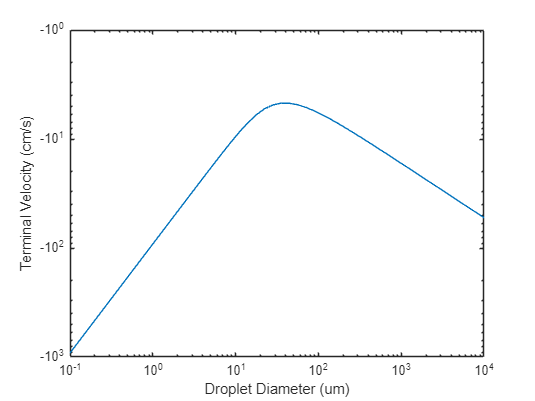

loglog(diameters_microns, v_neg)
xlim([10^-1, 10^4])
xlabel('Droplet Diameter (um)')
ylabel('Terminal Velocity (cm/s)')